# **P03: Funciones de Membresía**

## **Colaboradores**

- Fuentes Cendejas Héctor Tomás

## **Objetivos**

- Implementar operaciones de conjuntos difusos, utilizando MATLAB.

- Implementar transformaciones de conjuntos difusos, utilizando MATLAB.

## Introducción

En gran parte de los casos, es dificil clasificar los objetos del mundo real precisamente en un criterio específico de membresía. Si queremos clasificar a animales tales como perros, gatos, reptiles, aves, sabemos que podemos agregarles un valor de pertenencia a su determinado conjunto de manera total.

Pero, ¿que sucede con las estrellas de mar, bacterias, o cualquier ser vivo que pueda considerarse en más de una categoría debido a sus características? Estas situaciones las podemos encontrar en múltiples ocasiones de la vida diaria. En el caso de la ingeniería biónica, el objeto principal de estudio es el ser humano. 

A diferencia de las máquinas, las cuales toman decisiones tajantes basadas en ceros y unos (que en este caso tomamos como pertenencia o no pertenencia), la clave del acercamiento de los conjuntos difusos esta basada en la premisa de que, precisamente, el pensamiento humano dista de ser tajante, como el de las máquinas, para ser considerado como etiquetas de conjuntos difusos, en otras palabras, clases de objetos en donde la transición de pertenencia a no pertenencia es gradual en vez de abrupta. De hecho, el proceso del pensamiento humano sugiere que mucha de la lógica detrás del razonamiento esta basada en verdades difusas, conexiones difusas, y reglas difusas.

Con esto podemos dar por entendido la importancia de la lógica difusa como herramienta de la ingeniería.

## Problema 1 

**Investiga la expresión matemática para la función***** smf*** **y la función *****psigmf. *****Reporta dichas expresiones.**

### **Función smf**

La función *smf (S-shaped curve) *es una función que acepta valores, junto con parámetros con la siguiente sintaxis: smf(X,PARAMS)  y los introduce en la siguiente expresión matemática para después graficarla.

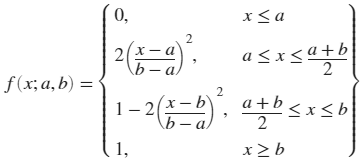

Como ejemplo tenemos el siguiente código

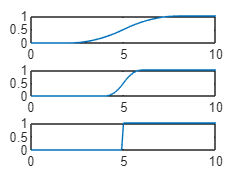

x = 0:0.1:10;
subplot(311); plot(x, smf(x,[2 8]));
subplot(312); plot(x, smf(x,[4 6]));
subplot(313); plot(x, smf(x,[6 4]));

### Función psigmf

La función *psigmf *es el prodcuto de dos funciones de membresía sigmoidales, la cual acepta también elementos y parámetros con la siguiente síntaxis: ***psigmf(X,PARAM)***. Cada función  sigmoidal tiene la siguiente expresión matemática:

 

En el siguiente código se generan dos funciones sigmoidales, para posteriormente ejecutar su producto por medio se la función referida


x = (0:0.2:10)';
params1 = [2 3];
y1 = sigmf(x, params1);
params2 = [-5 8];
y2 = sigmf(x, params2);
y3 = psigmf(x, [params1 params2]);
% subplot(211);
% plot(x, y1, x, y2); title('sigmf');
% subplot(212);
% plot(x, y3, 'g-'); title('psigmf');





## Problema 2

**Cree una función en MATLAB que reciba como argumentos de entrada el dominio y rango de una función de membresía.**